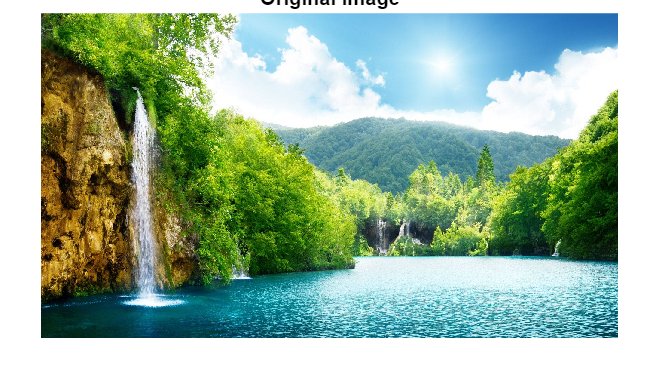

%read the image
img = imread("pic1.png");
% Convert image to grayscale
imgGray = im2gray(img);
figure;
imshow(img);
title("Original Image");

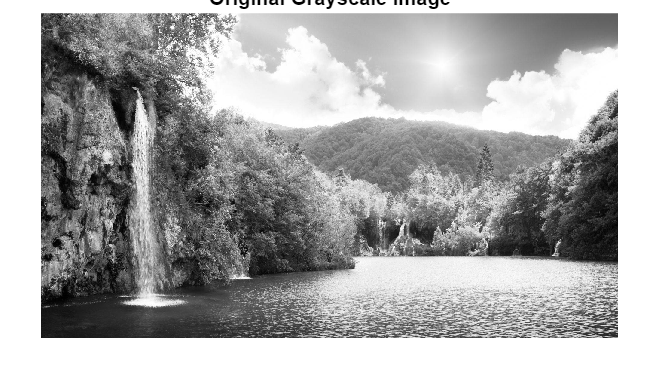

imshow(imgGray);
title("Original Grayscale Image");

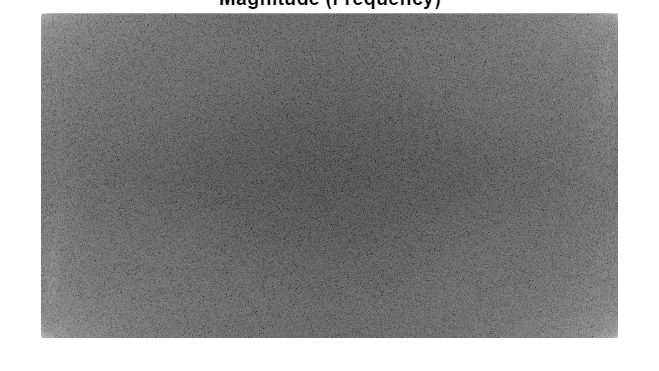

% Applying Fourier transform to the image
fourier_transform = fft2(imgGray);

% Calculating the magnitude and phase
magnitude = abs(fourier_transform);
phase = angle(fourier_transform);

% Display the frequency as an image
imshow(log(1 + magnitude), []);
title('Magnitude (Frequency)');

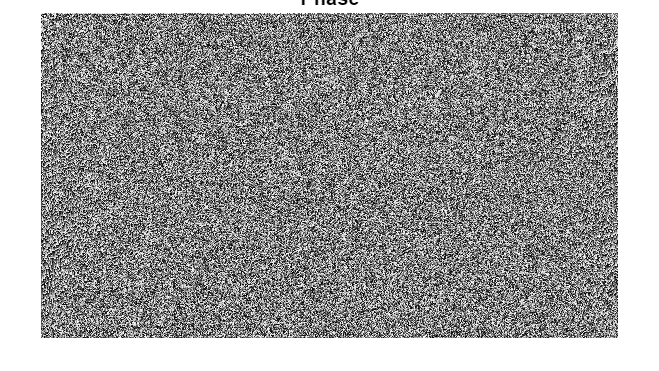


% Display the phase as an image
imshow(phase, []);
title('Phase');

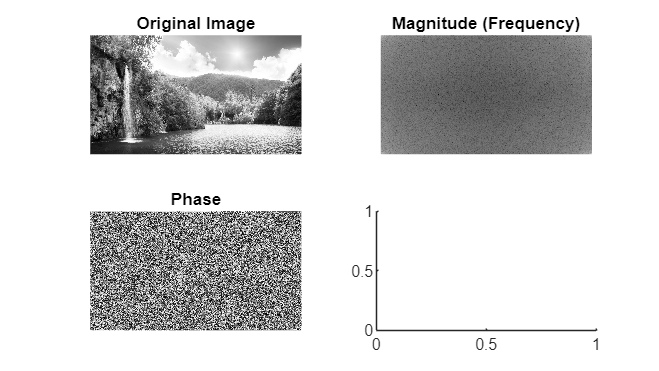

% Remove the low-frequency components from the Fourier coefficient matrix and reconstruct the image (imgR) 
% from the new Fourier coefficient matrix.
% To perform the above task a high pass filter 
% Define a threshold for removing low-frequency components
% threshold = 10;
% 
% % Remove low-frequency components by setting them to zero
% img1_fft_filtered = fourier_transform;
% img1_fft_filtered(1:threshold,1:threshold)=0;
% 
% % Reconstruct the image from the filtered Fourier coefficients
% imgR = ifft2(img1_fft_filtered);
% imgR = uint8(real(imgR)); % Convert back to uint8 data type

freqCutOff = 300;
% 
% % Create a high-pass filter so that it removes low frequency components.
[rows, cols] = size(magnitude);
high_pass_filter = ones(rows, cols);
high_pass_filter(rows/2 - freqCutOff:rows/2 + freqCutOff, cols/2 - freqCutOff:cols/2 + freqCutOff) = 0;
% 
% % Apply the high-pass filter to the magnitude
filtered_magnitude = magnitude .* high_pass_filter;
% 
% % Reconstructing the new Fourier coefficient matrix
new_fourier_transform = filtered_magnitude .* exp(1i * phase);
% 
% % Inverse Fourier transform to obtain the filtered image
filtered_image = ifft2(new_fourier_transform);

% Display the original image, magnitude (frequency), phase, and filtered image
subplot(2, 2, 1);
imshow(imgGray);
title('Original Image');

subplot(2, 2, 2);
imshow(log(1 + magnitude), []);
title('Magnitude (Frequency)');

subplot(2, 2, 3);
imshow(phase, []);
title('Phase');

subplot(2, 2, 4);

imshow(uint8(abs(img1_fft_filtered)));

Unrecognized function or variable 'img1_fft_filtered'.

title('Filtered Image');
% Show all images together
colormap gray;
sgtitle('Image, Fourier Transform, and Filtered Image');
% Display the reconstructed image (imgR)
figure;
imshow(uint8(abs(img1_fft_filtered)));
title('Reconstructed Image');
colormap gray;
% Construct and apply a spatial filter to img1 to match the reconstructed image imgR 
% Here in this block of code we implement a spacial filter to match the
% reconstrucetd image
filter_size = 5;
sigma = 1.5;

gaussian_filter = fspecial('gaussian', [filter_size, filter_size], sigma);

% Applying the Gaussian filter to the original image
filtered_img = imfilter(imgGray, gaussian_filter, 'replicate');

% Displaying the images
subplot(2, 2, 1);
imshow(imgGray);
title('Original Image');

subplot(2, 2, 2);
imshow(uint8(img1_fft_filtered));
title('Filtered Image (Gaussian)');

subplot(2,2, 3);
imshow(uint8(abs(img1_fft_filtered)));
title('Reconstructed Image');

colormap gray;
sgtitle('Image, Filtered Image, and Reconstructed Image');
% Compute and display the similarity score between the results of spatial filter and imgR
% Calculate SSIM between filtered image and imgR
ssim_score = ssim(uint8(filtered_img), uint8(abs(filtered_img)));

% Calculating Mean Squared Error (MSE) between filtered image and imgR
mse = immse(uint8(filtered_img), uint8(abs(filtered_img)));
fprintf('SSIM Score: %.4f\n', ssim_score);
fprintf('MSE: %.4f\n', mse);

% Displaying the images for visual comparison
figure;
subplot(1, 2, 1);
imshow(uint8(filtered_img));
title('Filtered Image (Gaussian)');

subplot(1, 2, 2);
imshow(uint8(abs(filtered_img)));
title('Reconstructed Image');

% Show both images side by side
colormap gray;
sgtitle('Filtered Image and Reconstructed Image');